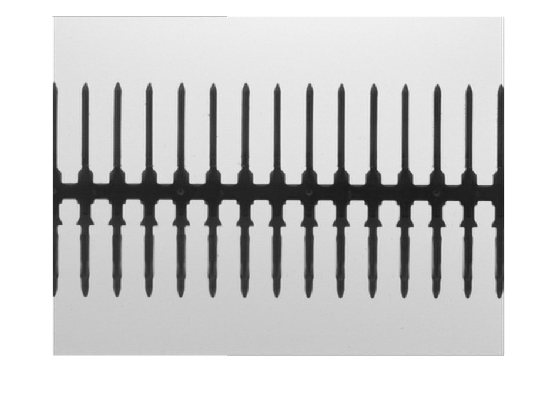

I = imread("Pin 1.jpg");
imshow(I);

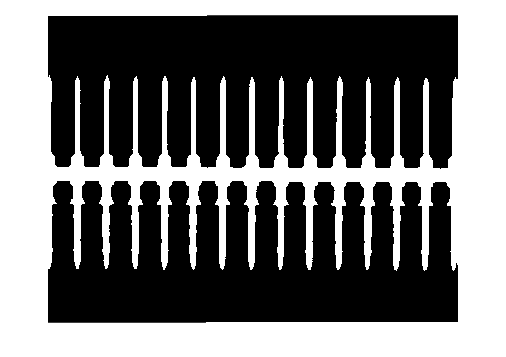

BW = I < 100;
imshow(BW)

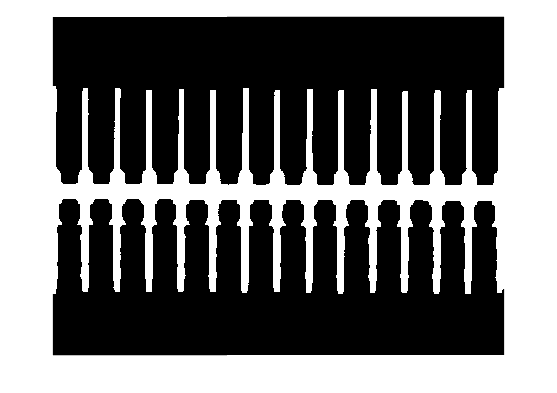

se = strel("line",9,0);
E = imopen(BW,se);
imshow(E);

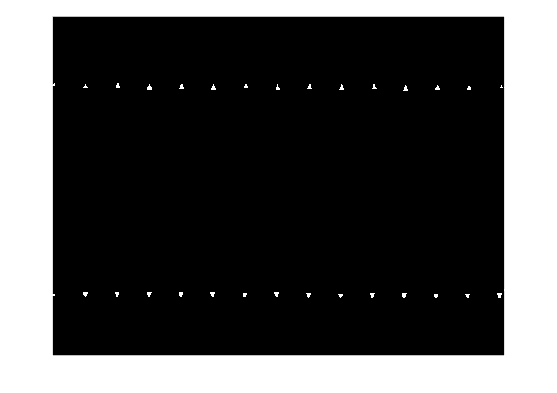

R = BW - E;
imshow(R);

bwconncomp(R)

ans = struct with fields:
    Connectivity: 8
       ImageSize: [576 768]
      NumObjects: 32
    PixelIdxList: {1×32 cell}
